# Racing Line Optimizer

### Import track data

track = readmatrix("Spa.csv")

track = 1.0e+03 *

   -0.0002    0.0021    0.0067    0.0069
   -0.0029    0.0063    0.0067    0.0068
   -0.0055    0.0105    0.0067    0.0068
   -0.0082    0.0148    0.0067    0.0068
   -0.0109    0.0190    0.0067    0.0068
   -0.0135    0.0232    0.0067    0.0068
   -0.0162    0.0275    0.0067    0.0068
   -0.0188    0.0317    0.0067    0.0068
   -0.0215    0.0359    0.0067    0.0068
   -0.0241    0.0402    0.0067    0.0068


### Define variables

trackName = 'Spa';
m = 750; % Mass of vehicle
ftmax = 16; % Max acceleration (m/s^2)
fbmax = 18; % Min acceleration (m/s^2)
fnmax = 30; % Max cornering acceleration (m/s^2)

### Generate optimized path

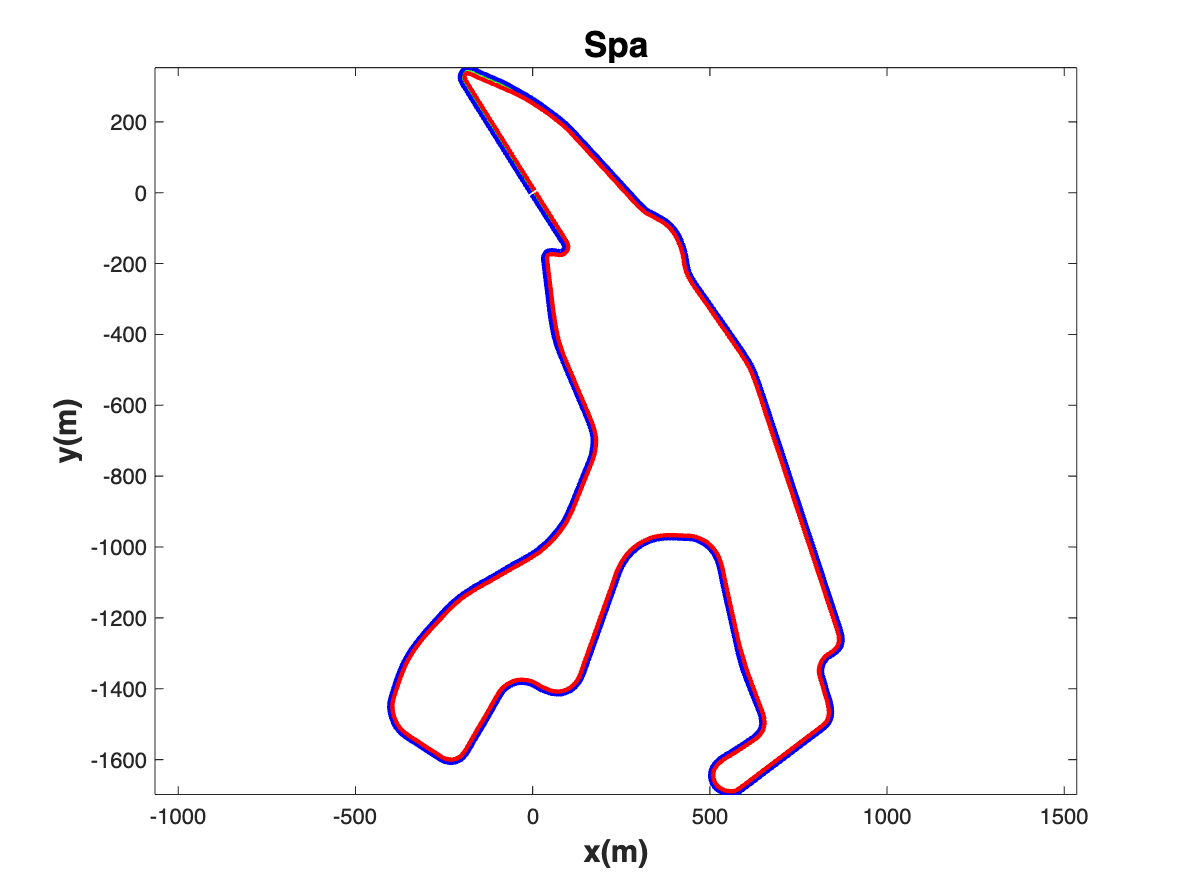

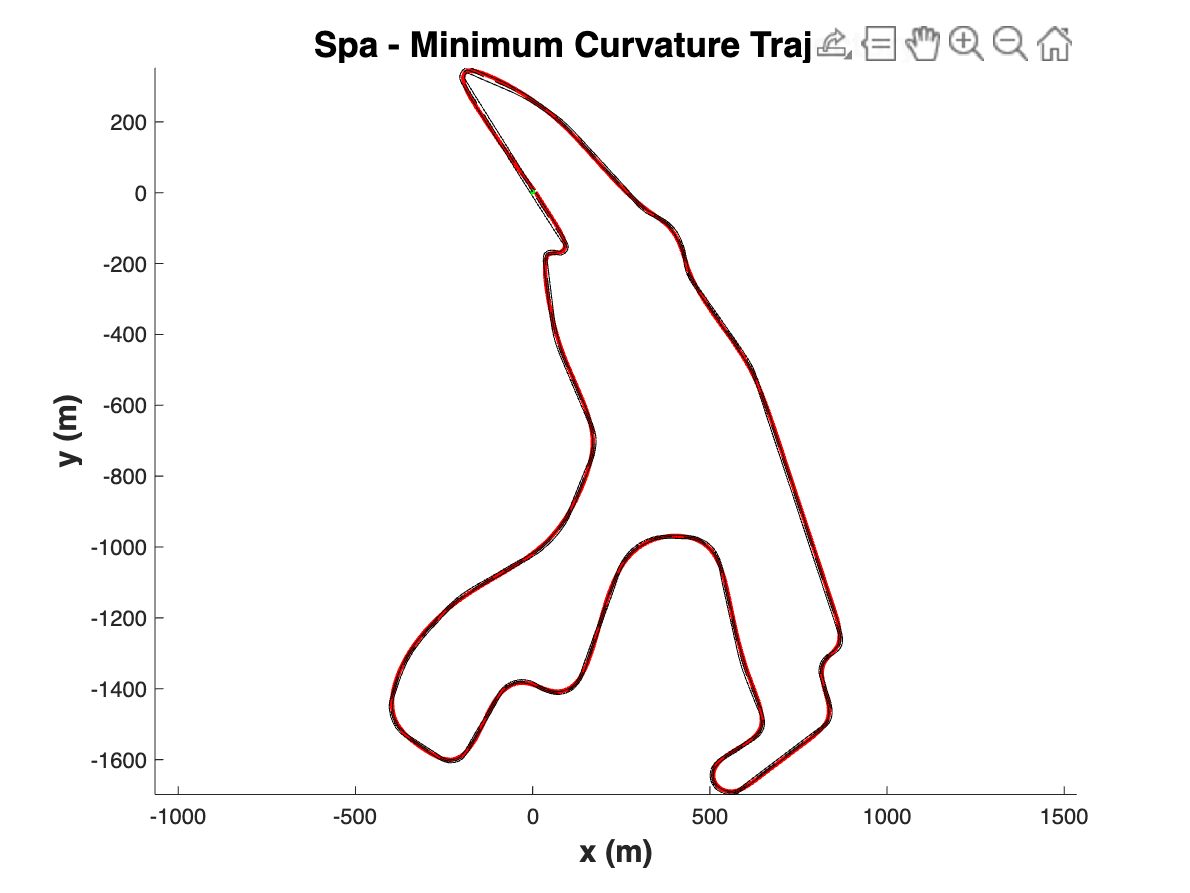

[raceline, final_centerline, x_in, y_in, x_out, y_out] = get_opt_raceline(track,trackName);

### Generate velocity profile

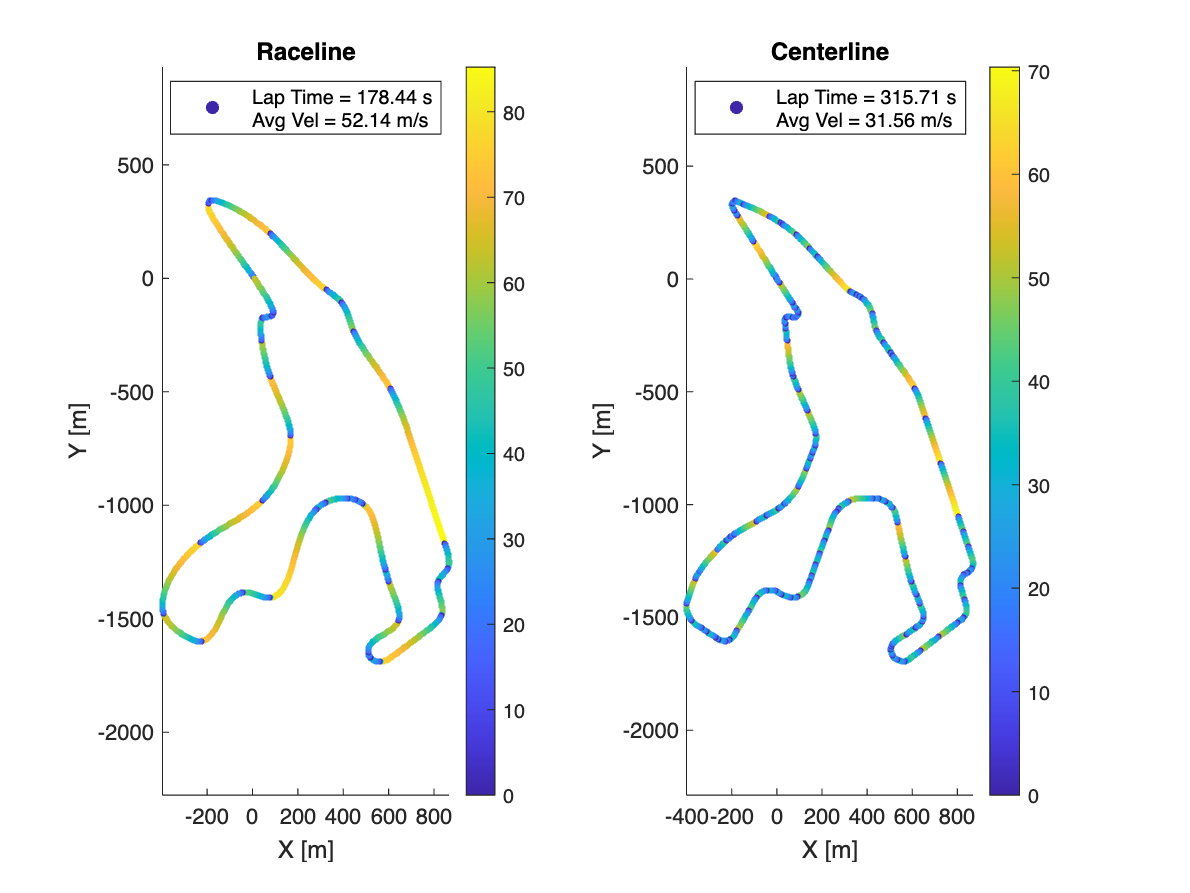

[velProf,len] = get_velseq(raceline, final_centerline, trackName,m,ftmax,fbmax,fnmax,[raceline x_in x_out y_in y_out]);

### References:

- The Silverstone racetrack data has been taken from the following GitHub repository: [https://github.com/TUMFTM/racetrack-database](https://github.com/TUMFTM/racetrack-database) 

- The function, "get_velseq" uses the function, "get_curvature" that has been taken from the following File Exchange: [https://www.mathworks.com/matlabcentral/fileexchange/69452-curvature-of-a-1d-curve-in-a-2d-or-3d-space](https://www.mathworks.com/matlabcentral/fileexchange/69452-curvature-of-a-1d-curve-in-a-2d-or-3d-space)

- All the code used here, including this live script, is either a direct copy or a rearrangement of the code in the following GitHub repository: [https://github.com/putta54/MW208_Raceline_Optimization/tree/main](https://github.com/putta54/MW208_Raceline_Optimization/tree/main)

- Final note: all credit of this solution goes to the owner of [https://github.com/putta54/MW208_Raceline_Optimization/tree/main](https://github.com/putta54/MW208_Raceline_Optimization/tree/main) , I have only studied and rearranged it for personal learning purposes.